# **LAB5 滤波器**

#### 应逸雯12210159 陈薇羽12210460

### 通过本实验的练习，掌握了以下技能：

1、butter函数——自选频率构造滤波器

2、rand函数——生成随机信号

3、fir函数（fir1、fir2）——基于window函数的滤波器

4、pwelch函数——功率谱密度估计

5、生成信号包络

6、norm函数——用于归一化能量，调整信噪比

7、audio操作

### 作业内容

#### 1.生成语谱噪声，画出原信号的谱、噪声的谱。

导入原信号：[y, fs] = audioread(filename)

生成长周期频谱：sig = repmat(sig,1,10); [Pxx,w] = pwelch(sig,Windows,noverlap,nfft,fs); plot(w,Pxx); 其中还用到参数nfft=512; noverlap = nfft/2; Windows = hamming(nfft);

生成滤波器参数：b = fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx))); [h,wh] = freqz(b,1,128);

生成白噪声：N=length(x); noise = 1-2*rand(1,N); y= filter(b,1,noise);

clc,clear,close all;
%导入原信号
[x1,fs1]=audioread('C_01_01.wav');
[x2,fs2]=audioread('C_01_02.wav');
t1=linspace(0,length(x1)/fs1,length(x1));
t2=linspace(0,length(x2)/fs2,length(x2));
%播放确认导入无误
%sound(x1,fs1);
%sound(x2,fs2);
%画图
figure;
disp('原信号');

原信号


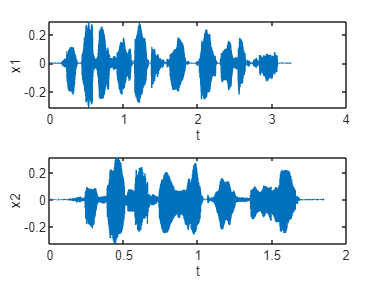

subplot(2,1,1),plot(t1,x1),xlabel('t'),ylabel('x1');
subplot(2,1,2),plot(t2,x2),xlabel('t'),ylabel('x2');

%设定参数
nfft=512;
noverlap=nfft/2;
Windows=hamming(nfft);
%产生更长的信号
x1long=repmat(x1,1,10);
x2long=repmat(x2,1,10);
%计算频谱密度
[Pxx1,w1]=pwelch(x1long,Windows,noverlap,nfft,fs1);
[Pxx2,w2]=pwelch(x2long,Windows,noverlap,nfft,fs2);
%生成滤波器参数
b1=fir2(3000,w1/(fs1/2),sqrt(Pxx1/max(Pxx1)));
b2=fir2(3000,w1/(fs2/2),sqrt(Pxx2/max(Pxx2)));
[h1,wh1]=freqz(b1,1,128);
[h2,wh2]=freqz(b2,1,128);
%生成白噪声
N1=length(x1);
noisebase1=1-2*rand(1,N1);
N2=length(x2);
noisebase2=1-2*rand(1,N2);
noise1=filter(b1,1,noisebase1);
noise2=filter(b2,1,noisebase2);
%画图
figure;
disp('语谱噪声-时域');

语谱噪声-时域


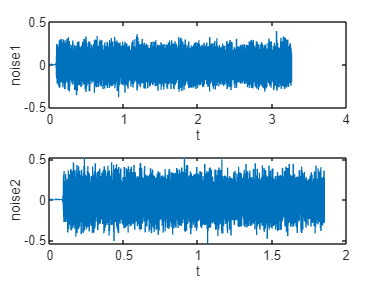

subplot(2,1,1),plot(t1,noise1),xlabel('t'),ylabel('noise1');
subplot(2,1,2),plot(t2,noise2),xlabel('t'),ylabel('noise2');

得到信号如图。

#### 2.调整信噪比至-5dB，读语音信号x，标准化能量，为y，画出

信噪比公式：SNR=20*log10(norm(sig)/norm(noise))

-5dB <=> norm(sig)/norm(noise)=10^(-0.25)

调整能量：y’=y/norm(y)*norm(x)*2; % then y' has the twice energy of x

%得到噪声
soundnoise1=noise1/norm(noise1)*norm(x1)*(10^0.25);
soundnoise1=soundnoise1+x1.';
soundnoise2=noise2/norm(noise2)*norm(x2)*(10^0.25);
soundnoise2=soundnoise2+x2.';
%得到能量不变的带噪声信号
y1=soundnoise1/norm(soundnoise1)*norm(x1);
y2=soundnoise2/norm(soundnoise2)*norm(x2);
%画图
figure;
disp('带噪声的信号');

带噪声的信号


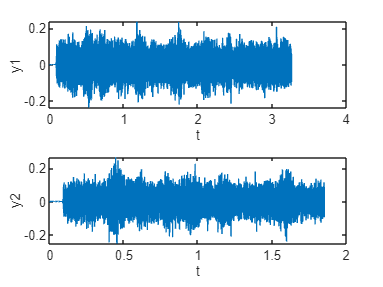

subplot(2,1,1),plot(t1,y1),xlabel('t'),ylabel('y1');
subplot(2,1,2),plot(t2,y2),xlabel('t'),ylabel('y2');

得到信号如图。

#### 3.(1)用截止频率分别为100，200，300Hz的Butterworth滤波器，绘制包络信号（此处输入信号为原信号）

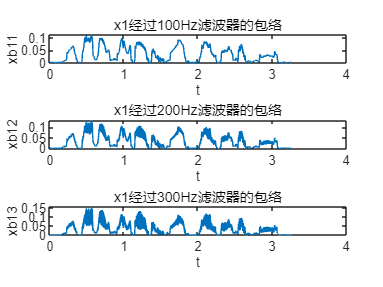

[b1,a1]=butter(2,100/fs1*2);
[b2,a2]=butter(2,200/fs1*2);
[b3,a3]=butter(2,300/fs1*2);
x1=x1.';
x2=x2.';
%输入信号为x1
xb11=filter(b1,a1,abs(x1));
xb12=filter(b2,a2,abs(x1));
xb13=filter(b3,a3,abs(x1));
%输入信号为x2
xb21=filter(b1,a1,abs(x2));
xb22=filter(b2,a2,abs(x2));
xb23=filter(b3,a3,abs(x2));

%因为三个包络信号画在同一张图上难以区分，所以将三种滤波器的包络信号绘制在三张subplot上
figure
subplot(3,1,1);
plot(t1,xb11);title('x1经过100Hz滤波器的包络');xlabel('t');ylabel('xb11')
subplot(3,1,2);
plot(t1,xb12);title('x1经过200Hz滤波器的包络');xlabel('t');ylabel('xb12')
subplot(3,1,3);
plot(t1,xb13);title('x1经过300Hz滤波器的包络');xlabel('t');ylabel('xb13')

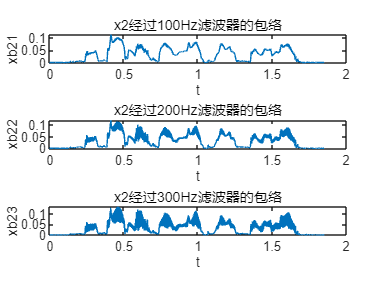

figure
subplot(3,1,1);
plot(t2,xb21);title('x2经过100Hz滤波器的包络');xlabel('t');ylabel('xb21')
subplot(3,1,2);
plot(t2,xb22);title('x2经过200Hz滤波器的包络');xlabel('t');ylabel('xb22')
subplot(3,1,3);
plot(t2,xb23);title('x2经过300Hz滤波器的包络');xlabel('t');ylabel('xb23')

如图所示，阶数相同时，截止频率越高，包络函数高频部分保留越多，失真越少

#### 3.(2)用截止频率分别为100，200，300Hz的Butterworth滤波器，绘制包络信号（此处输入信号为原信号）

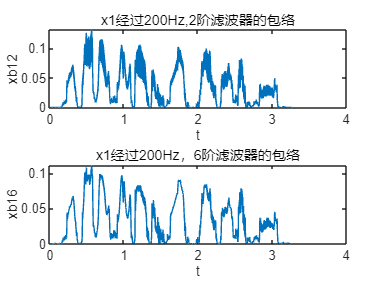

[b6,a6]=butter(6,200/fs1*2);
xb16=filter(b6,a6,abs(x1));
xb26=filter(b6,a6,abs(x2));
figure
subplot(2,1,1);
plot(t1,xb12);title('x1经过200Hz,2阶滤波器的包络');xlabel('t');ylabel('xb12');
subplot(2,1,2);
plot(t1,xb16);title('x1经过200Hz，6阶滤波器的包络');xlabel('t');ylabel('xb16');

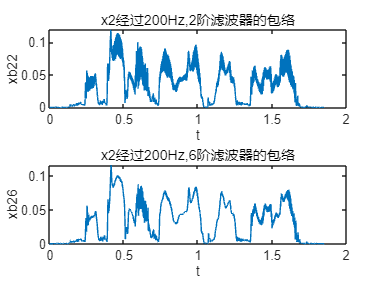

figure
subplot(2,1,1);
plot(t2,xb22);title('x2经过200Hz,2阶滤波器的包络');xlabel('t');ylabel('xb22');
subplot(2,1,2);
plot(t2,xb26);title('x2经过200Hz,6阶滤波器的包络');xlabel('t');ylabel('xb26');

如图所示，截止频率相同时，阶数更高的滤波器对高频信号的过滤程度更高，即保留的高频信号更少

#### 4.录制一段音频并存储为.wave文件

recObj = audiorecorder(11025,8,1);
disp('Start speaking.')

Start speaking.


recordblocking(recObj, 5);
disp('End of Recording.');

End of Recording.


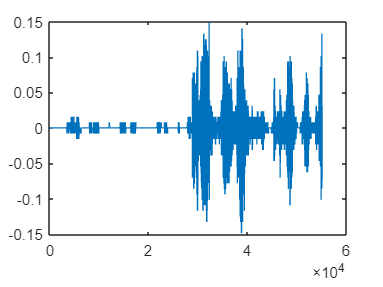

% 回放录音数据
play(recObj);
% 获取录音数据
myRecording = getaudiodata(recObj);
% 绘制录音数据波形
figure
plot(myRecording);

%存储语音信号
filename = 'data1.wav'; 
audiowrite(filename,myRecording,11025);

#### 课堂参与证明：

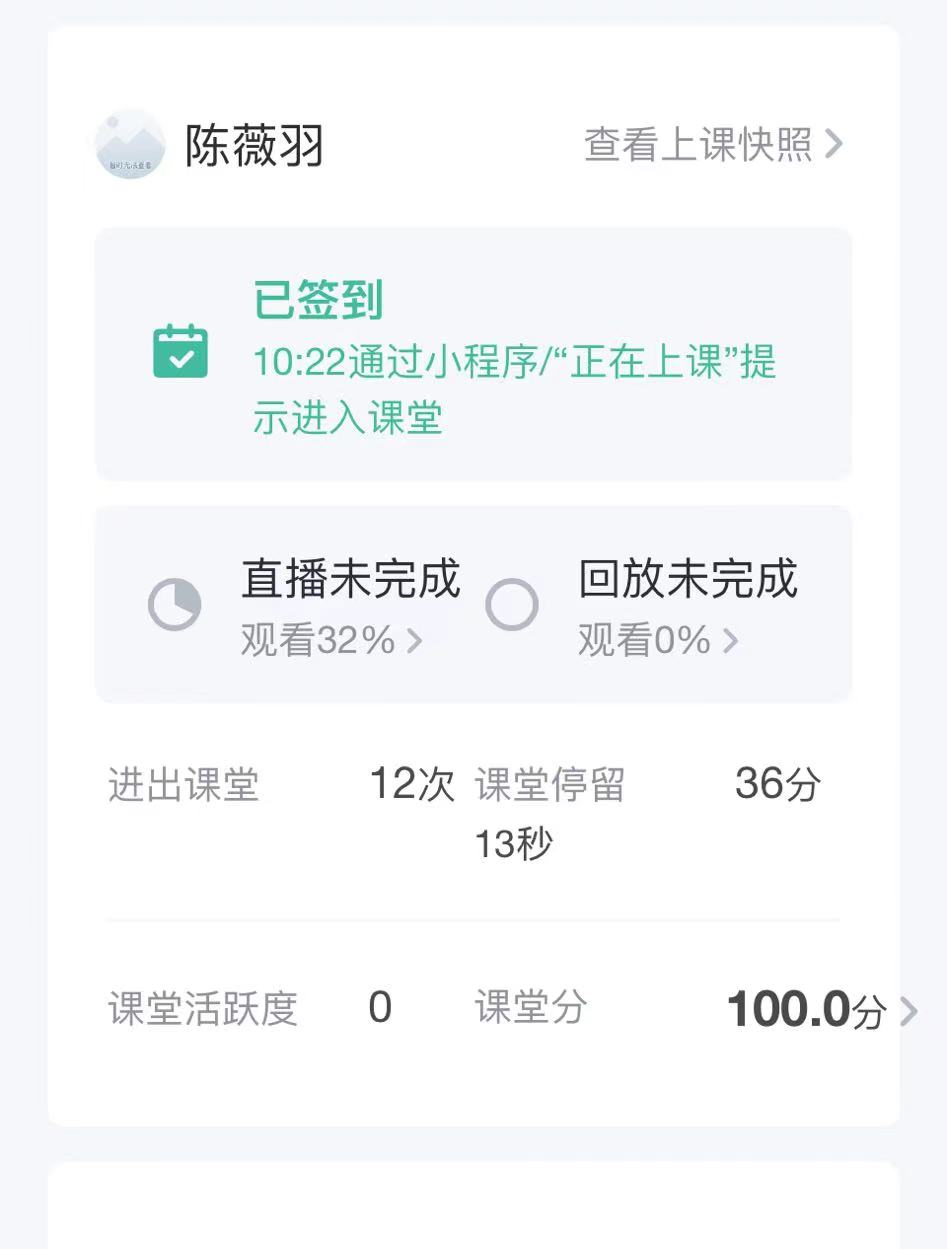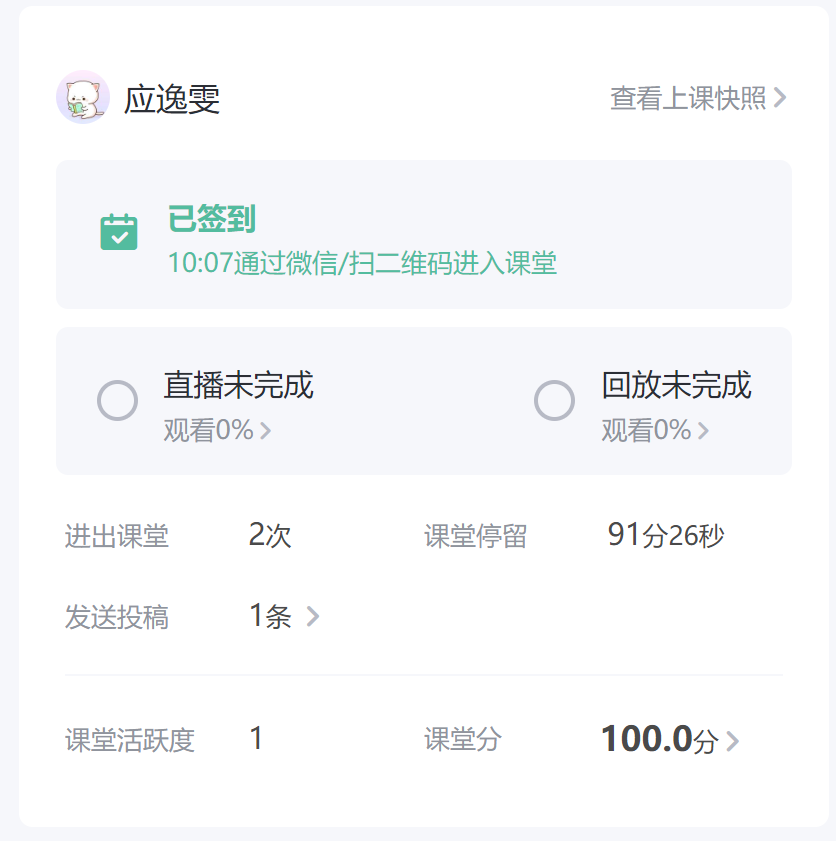

#### 自我评分：

应逸雯：10/10

陈薇羽：10/10